% Author: Gerardo Parra
clear

%% parameters for running batch script
% parameters for loading data
task      = 'tss';
beapp_tag = '_25hzLP_32hzNF';
file_tag  = [beapp_tag '_2023-04-28_gp']; % _rise-decay_avg
data_path = fullfile( 'X:','Groups','SPA','01_Data_Raw_Summary_Processed', ...
                      'EEG','Participant_Data','03_Processed_Data' );

% parameters for processing
groups    = {'TD','ASD','SPC'};
method    = 'conds_avg';
rois      = {'E30E36E41'};
erps      = {'P50','P100','N140','P300','P4','P100_N140_dist','N140_P300_dist','P4_N140_dist'};  % components to calculate/plot
exclude   = {};
erps      = {'P50','P100','N140','P300'}; %'P100_N140_dist','N140_P300_dist','P4'};
erp_times = [75 175 275 300];

% parameters for plots
groups_to_plot = 1:2;
corr_type      = 'Spearman';
coeff          = 'm_peak_ct';
save_figs   = false;
norm_data   = false;
rm_outliers = false;
colors      = {'#4444c9','#32a852','#e69a0e'};
markers     = {'o','+','*'};

  

% parameters for sp2 table
sp2_path   = fullfile(data_path,'01_Subject_Info_For_Processing','SP2_Processed_2023-04-28');
sp2_fields = {                              ...
                'scq_total',                ...
                'Tactile Modality',         ...
                'Tactile Hyper-reactivity', ...
                'Tactile Hypo-reactivity',  ...
                'Seeking Domain',           ...
                'Attentional Modality',     ...
                'Avoiding Domain',          ...
                'Sensitivity Domain',       ...
                'Registration Domain'       ...
           };

%% load batch information
task_path = get_task_path(task);
task_path_batch = fullfile(data_path,task_path,'erp',['erp' file_tag '.mat']);
load(task_path_batch,'batch');
if norm_data, method = [method '_norm']; end
batch.method = method;
% get save path
save_path = fullfile(data_path,task_path,'figures','erp_indiv');
if ~exist(save_path,'dir'), mkdir(save_path); end
% get method name for plots/saving
method_name = get_method_plot_name(method);

%% load and clean sp2 table
sp2_table = readtable(sp2_path,'PreserveVariableNames',true);
sp2_table = rmmissing(sp2_table);

%% calculate suppression, then find slopes
[data,batch] = calc_si_by_indiv(batch,exclude,erps,1);
slopes = calculate_erp_slopes(data,groups,rois,erp_times);

## Plot correlations

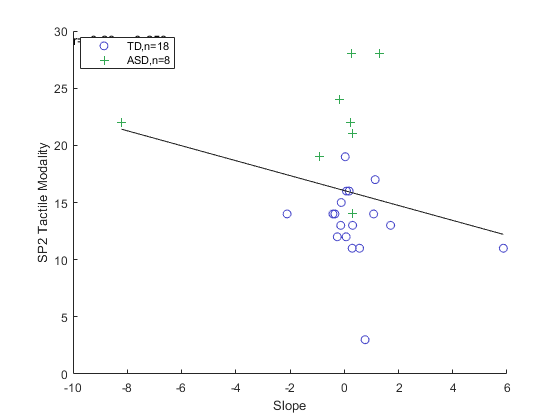

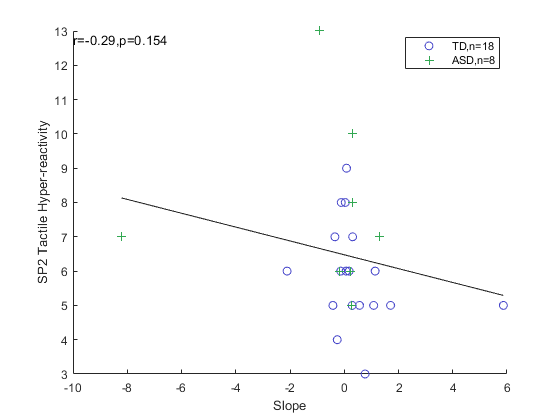

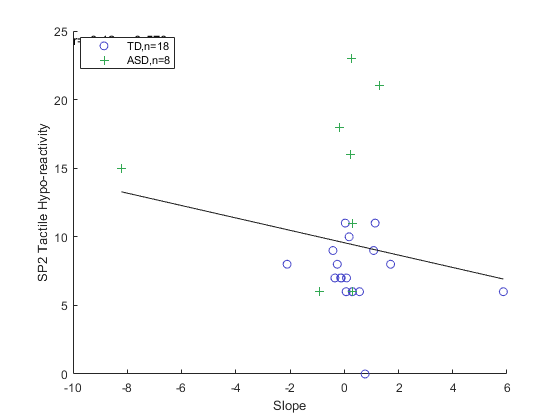

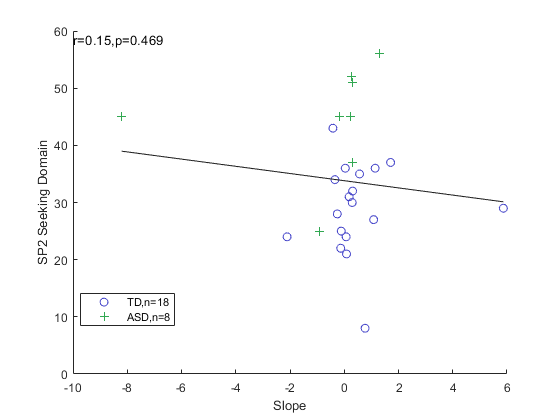

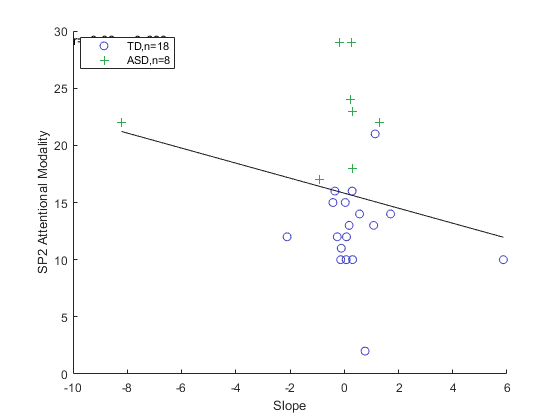

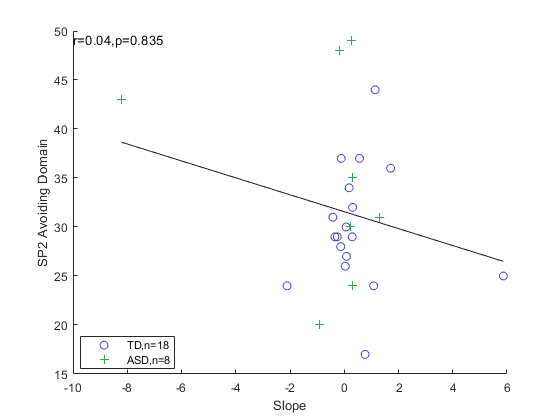

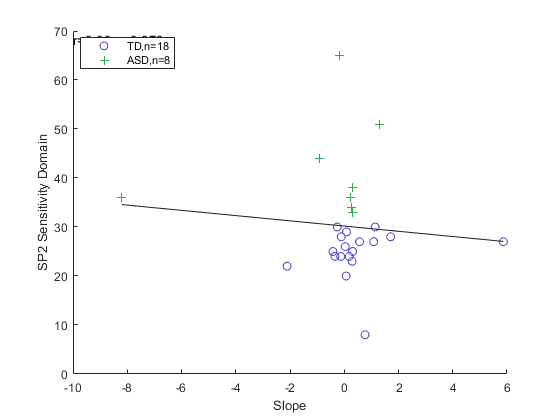

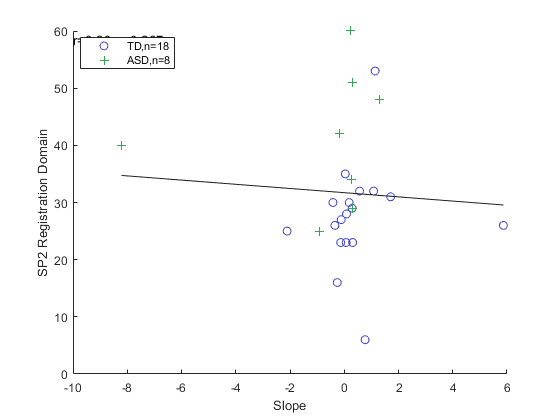

n_fields = length(sp2_fields);
n_groups = length(groups_to_plot);

% iterate through sp2 fields
for i_m = 1:n_fields
    field = sp2_fields{i_m};
    % iterate through rois
    for i_r = 1:length(rois)
        roi = rois{i_r};
        % intialize plot
        figure, hold on
        xlabel('Slope'), ylabel(plaintext(['SP2 ' field]))

        % iterate through groups
        plot_eeg = cell(1,n_groups); plot_sp2 = plot_eeg;
        grp_label = plot_eeg;
        for i_g = groups_to_plot
            % get eeg data from current group
            group   = groups{i_g};
            grp_eeg = slopes.(roi);
            grp_eeg = grp_eeg([grp_eeg.group] == i_g);

            % get ids in sp2 and eeg tables
            ids_eeg = [grp_eeg.id]; ids_sp2 = [sp2_table.study_id];
            ids = intersect(ids_sp2,ids_eeg)';
            grp_label{i_g} = plaintext([group ',n=' int2str(length(ids))]);

            % add sp2 measures to slopes table
            for i = ids
                i_eeg = [slopes.(roi).id] == i;
                i_sp2 = ids_sp2 == i;
                st_fld = validate_fieldname(field);
                slopes.(roi)(i_eeg).(st_fld) = sp2_table.(field)(i_sp2);
            end

            % scatter eeg and sp2
            plot_eeg{i_g} = [grp_eeg(ismember(ids_eeg,ids)).(coeff)]';
            plot_sp2{i_g} = [sp2_table.(field)(ismember(ids_sp2,ids))];
            scatter( plot_eeg{i_g}, plot_sp2{i_g}, 'Marker', markers{i_g},    ...
                     'MarkerEdgeColor', colors{i_g} )
        end
        plot_eeg = cell2mat(plot_eeg'); 
        plot_sp2 = cell2mat(plot_sp2');
        
         % remove outliers, if selected
        if rm_outliers
            out_eeg  = abs(zscore(plot_eeg)) > 3;
            out_sp2  = abs(zscore(plot_sp2)) > 3;
            outliers = logical(out_eeg + out_sp2);
            plot_eeg(outliers) = []; plot_sp2(outliers) = [];
        end

        % get line of best fit
        pf    = polyfit(plot_eeg,plot_sp2,1);
        y_fit = polyval(pf,plot_eeg);
        plot(plot_eeg,y_fit,'Color','#222')

        % shrink legend and move off of plots
        legend(grp_label{groups_to_plot},'Location','best');

        % correlate measures
        [r,pf] = corr(plot_eeg,plot_sp2,'Type',corr_type);
        str=sprintf('r=%1.2f,p=%1.3f',r,pf);
        T = text(min(get(gca,'xlim')), max(get(gca,'ylim')), str); 
        set(T,'fontsize',10,'verticalalignment','top','horizontalalignment','left');
    end
end